**Practica 03 Mathematics - MATLAB**

**Nombre: **Fernando Eliceo Huilca Villagomez  **                  Fecha: **28/01/2024

% Encabezado...
disp('-----------------------------------------------');

-----------------------------------------------


disp('Practica 03 Mathematics - MATLAB');

Practica 03 Mathematics - MATLAB


disp('-----------------------------------------------');

-----------------------------------------------


disp('  Nombre: Fernando Huilca');

  Nombre: Fernando Huilca


disp('  Fecha: 28/01/2024');

  Fecha: 28/01/2024


disp('  Profesor: Andrés Larco');

  Profesor: Andrés Larco


## Álgebra lineal

El entorno MATLAB utiliza el término matriz para indicar una variable que contiene valores reales o complejos.números dispuestos en una cuadrícula bidimensional. Una matriz es, más generalmente, un vector, una matriz o superior.cuadrícula dimensional de números. Todas las matrices en MATLAB son rectangulares, en el sentido de que el componentelos vectores a lo largo de cualquier dimensión tienen todos la misma longitud. Las operaciones matemáticas definidas enLas matrices son el tema del álgebra lineal.

### Creando matrices

MATLAB tiene muchas funciones que crean diferentes tipos de matrices. Por ejemplo, puedes crear unmatriz simétrica con entradas basadas en el triángulo de Pascal:

A = pascal(3)

A =      1     1     1
     1     2     3
     1     3     6


O bien, puedes crear una matriz cuadrada mágica asimétrica, que tenga sumas iguales de filas y columnas:

B = magic(3)

B =      8     1     6
     3     5     7
     4     9     2


Otro ejemplo es una matriz rectangular de 3 por 2 de números enteros aleatorios. En este caso la primera entrada arandi describe el rango de valores posibles para los números enteros, y las dos segundas entradas describen elnúmero de filas y columnas.

C = randi(10,3,2)

C =      2     3
     9     5
    10     5


Un vector de columna es una matriz de m por 1, un vector de fila es una matriz de 1 por n y un escalar es una matriz de 1 por 1.Para definir una matriz manualmente, utilice corchetes [] para indicar el principio y el final de la matriz.Dentro de los corchetes, utilice un punto y coma; para indicar el final de una fila. En el caso de un escalar (1 por 1matriz), los corchetes no son necesarios. Por ejemplo, estas declaraciones producen un vector columna, una filavector y un escalar:

u = [3; 1; 4]

u =      3
     1
     4


v = [2 0 -1]

v =      2     0    -1


s = 7

s = 7

## Sumar y restar matrices

La suma y resta de matrices y matrices se realiza elemento por elemento o elemento por elemento.Por ejemplo, sumando A a B y luego restando A del resultado se recupera B:

X = A + B

X =      9     2     7
     4     7    10
     5    12     8


Y = X - A

Y =      8     1     6
     3     5     7
     4     9     2


## Productos vectoriales y transposición

Un vector fila y un vector columna de la misma longitud se pueden multiplicar en cualquier orden. El resultado esya sea un escalar, llamado producto interno, o una matriz, llamada producto externo:

u = [3; 1; 4];
v = [2 0 -1];
x = v*u

x = 2

X = u*v

X =      6     0    -3
     2     0    -1
     8     0    -4


Para matrices complejas, otroconsideración es si se debe tomar el conjugado complejo de entradas complejas en la matriz para formar eltranspuesta conjugada compleja. MATLAB utiliza el operador de apóstrofe (') para realizar un complejotransposición conjugada y el operador punto-apóstrofo (.') para transponer sin conjugación. 

Paramatrices que contienen todos los elementos reales, los dos operadores devuelven el mismo resultado.La matriz de ejemplo A = pascal(3) es simétrica, por lo que A' es igual a A. Sin embargo, B = magic(3) esno es simétrico, por lo que B' tiene los elementos reflejados a lo largo de la diagonal principal:

B = magic(3)

B =      8     1     6
     3     5     7
     4     9     2


X = B'

X =      8     3     4
     1     5     9
     6     7     2


Para vectores, la transposición convierte un vector fila en un vector columna (y viceversa):

x = v'

x =      2
     0
    -1


Si x e y son vectores columna reales, entonces el producto x*y no está definido, pero los dos productos

%% x' * y Comento esto porque sale el error "no esta definido"lo menciono en el texto de arriba
%% y' * x

producen el mismo resultado escalar. Esta cantidad se usa con tanta frecuencia que tiene tres nombres diferentes: interiorproducto, producto escalar o producto escalar. Incluso hay una función dedicada para productos escalables llamadapunto.

Para un vector o matriz complejo, z, la cantidad z' no sólo transpone el vector o matriz, sino tambiénconvierte cada elemento complejo en su conjugado complejo. Es decir, el signo de la parte imaginaria decada elemento complejo cambia. Por ejemplo, considere la matriz compleja

z = [1+2i 7-3i 3+4i; 6-2i 9i 4+7i]

z =    1.0000 + 2.0000i   7.0000 - 3.0000i   3.0000 + 4.0000i
   6.0000 - 2.0000i   0.0000 + 9.0000i   4.0000 + 7.0000i


z'

ans =    1.0000 - 2.0000i   6.0000 + 2.0000i
   7.0000 + 3.0000i   0.0000 - 9.0000i
   3.0000 - 4.0000i   4.0000 - 7.0000i


## Multiplicar matrices

La multiplicación de matrices se define de una manera que refleja la composición de la matriz lineal subyacente, transformaciones y permite la representación compacta de sistemas de ecuaciones lineales simultáneas. El producto matricial C = AB se define cuando la dimensión de la columna de A es igual a la dimensión de la fila de B,o cuando uno de ellos es un escalar. Si A es m por py B es p por n, su producto C es m por n. El productoEn realidad, se puede definir usando MATLAB para bucles, notación de dos puntos y productos de puntos vectoriales:

B = magic(3);
m = 3;
n = 3;
for i = 1:m
 for j = 1:n
 C(i,j) = A(i,:)*B(:,j);
 end
end

MATLAB utiliza un asterisco para indicar la multiplicación de matrices, como en C = A*B. La multiplicación de matrices no esconmutativo; es decir, A*B normalmente no es igual a B*A:

X = A*B

X =     15    15    15
    26    38    26
    41    70    39


Y = B*A

Y =     15    28    47
    15    34    60
    15    28    43


u = [3; 1; 4];
x = A*u

x =      8
    17
    30


v = [2 0 -1];
y = v*B

y =     12    -7    10


## Sistemas sobredeterminados

Este ejemplo muestra cómo a menudo se encuentran sistemas sobredeterminados en varios tipos de curvas.ajuste a los datos experimentales.Se mide una cantidad y en varios valores diferentes del tiempo t para producir las siguientes observaciones.Puede ingresar los datos y verlos en una tabla con las siguientes declaraciones.

t = [0 .3 .8 1.1 1.6 2.3]';
y = [.82 .72 .63 .60 .55 .50]';
B = table(t,y)

B = 6x2 table
     t      y  
    ___    ____

      0    0.82
    0.3    0.72
    0.8    0.63
    1.1     0.6
    1.6    0.55
    2.3     0.5


Intente modelar los datos con una función exponencial decreciente.

E = [ones(size(t)) exp(-t)]

E =     1.0000    1.0000
    1.0000    0.7408
    1.0000    0.4493
    1.0000    0.3329
    1.0000    0.2019
    1.0000    0.1003


c = E\y

c =     0.4760
    0.3413


Las siguientes declaraciones evalúan el modelo en incrementos regularmente espaciados en t, y luego trazan elresultado junto con los datos originales:

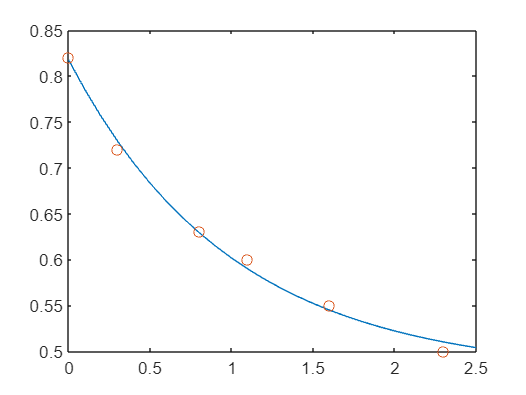

T = (0:0.1:2.5)';
Y = [ones(size(T)) exp(-T)]*c;
plot(T,Y,'-',t,y,'o')

## Sistemas indeterminados

Este ejemplo muestra cómo la solución a los sistemas indeterminados no es única. subdeterminadoLos sistemas lineales implican más incógnitas que ecuaciones. La operación de división de matriz por la izquierda en MATLABencuentra una solución básica de mínimos cuadrados, que tiene como máximo m componentes distintos de cero para un coeficiente m por nmatriz.Aquí hay un pequeño ejemplo aleatorio:

R = [6 8 7 3; 3 5 4 1]

R =      6     8     7     3
     3     5     4     1


rng(0);
b = randi(8,2,1)

b =      7
     8


El sistema lineal Rp = b implica dos ecuaciones con cuatro incógnitas. Desde la matriz de coeficientescontiene números enteros pequeños, es apropiado usar el comando format para mostrar la solución enformato racional.

format rat
p = R\b

p =        0       
      17/7     
       0       
     -29/7     


Z = null(R,'r')

Z =       -1/2           -7/6     
      -1/2            1/2     
       1              0       
       0              1       


q = [-2; 1];
x = p + Z * q;
format short
norm(R * x - b)

ans = 0

p = lsqminnorm(R,b)

p =    -1.5109
    2.6642
    0.5766
   -3.0949


## Factorizaciones

### Introducción

Las tres factorizaciones matriciales analizadas en esta sección utilizan matrices triangulares, donde todos los elementos por encima o por debajo de la diagonal son cero. 

### Factorización de Cholesky

La factorización de Cholesky expresa una matriz simétrica como el producto de una matriz triangular y sutransponerA = R′R,donde R es una matriz triangular superior.No todas las matrices simétricas pueden factorizarse de esta forma; las matrices que tienen tal factorizaciónse dice que son positivos definidos. Esto implica que todos los elementos diagonales de A son positivos y quelos elementos fuera de la diagonal "no son demasiado grandes". Las matrices de Pascal proporcionan un ejemplo interesante.A lo largo de este capítulo, la matriz A de ejemplo ha sido la matriz Pascal de 3 por 3. cambiar temporalmenteal 6 por 6:

A = pascal(6)

A =      1     1     1     1     1     1
     1     2     3     4     5     6
     1     3     6    10    15    21
     1     4    10    20    35    56
     1     5    15    35    70   126
     1     6    21    56   126   252


R = chol(A)

R =      1     1     1     1     1     1
     0     1     2     3     4     5
     0     0     1     3     6    10
     0     0     0     1     4    10
     0     0     0     0     1     5
     0     0     0     0     0     1


## Factorización LU

La factorización LU, o eliminación gaussiana, expresa cualquier matriz cuadrada A como el producto de unpermutación de una matriz triangular inferior y una matriz triangular superiorA = LU,donde L es una permutación de una matriz triangular inferior con unos en su diagonal y U es una matriz superiormatriz triangular.

Por ejemplo: 

B = magic(3);
[L,U] = lu(B)

L =     1.0000         0         0
    0.3750    0.5441    1.0000
    0.5000    1.0000         0


U =     8.0000    1.0000    6.0000
         0    8.5000   -1.0000
         0         0    5.2941


## Factorización QR

Una matriz ortogonal, o una matriz con columnas ortonormales, es una matriz real cuyas columnas tienen todas longitud unitaria y son perpendiculares entre sí. Si Q es ortogonal, entonces QTQ = yo,donde I es la matriz identidad.Las matrices ortogonales más simples son rotaciones de coordenadas bidimensionales:cos(θ) sen(θ)−sen(θ) cos(θ)

La factorización ortogonal o QR expresa cualquier matriz rectangular como el producto de unamatriz ortogonal o unitaria y una matriz triangular superior. Una permutación de columnas también podría serinvolucrado:A = QRoAP = QR,donde Q es ortogonal o unitario, R es triangular superior y P es una permutación.

C=gallery('uniformdata',[5 4], 0);
[Q,R] = qr(C)

Q =    -0.6191   -0.1406    0.1899   -0.5058   -0.5522
   -0.1506   -0.4084   -0.5034    0.5974   -0.4475
   -0.3954    0.5564   -0.6869   -0.1478    0.2008
   -0.3167   -0.6676   -0.1351   -0.1729    0.6370
   -0.5808    0.2410    0.4695    0.5792    0.2207


R =    -1.5346   -1.0663   -1.2010   -1.4036
         0   -0.7245   -0.3474    0.0126
         0         0   -0.9320   -0.6596
         0         0         0    0.6648
         0         0         0         0


[Q,R] = qr(C,0)

Q =    -0.6191   -0.1406    0.1899   -0.5058
   -0.1506   -0.4084   -0.5034    0.5974
   -0.3954    0.5564   -0.6869   -0.1478
   -0.3167   -0.6676   -0.1351   -0.1729
   -0.5808    0.2410    0.4695    0.5792


R =    -1.5346   -1.0663   -1.2010   -1.4036
         0   -0.7245   -0.3474    0.0126
         0         0   -0.9320   -0.6596
         0         0         0    0.6648


[Q,R,P] = qr(C)

Q =    -0.2404    0.5849   -0.1207    0.5297   -0.5522
   -0.5544   -0.0343   -0.0737   -0.6970   -0.4475
   -0.5434   -0.4896   -0.5272    0.3831    0.2008
   -0.2431    0.6454   -0.2655   -0.2193    0.6370
   -0.5296   -0.0236    0.7947    0.1967    0.2207


R =    -1.6874   -0.8816   -1.3607   -1.2765
         0    0.9406    0.3537    0.5433
         0         0   -0.6745    0.1277
         0         0         0    0.6435
         0         0         0         0


P =      0     0     0     1
     0     1     0     0
     0     0     1     0
     1     0     0     0


[Q,R,p] = qr(C,0)

Q =    -0.2404    0.5849   -0.1207    0.5297
   -0.5544   -0.0343   -0.0737   -0.6970
   -0.5434   -0.4896   -0.5272    0.3831
   -0.2431    0.6454   -0.2655   -0.2193
   -0.5296   -0.0236    0.7947    0.1967


R =    -1.6874   -0.8816   -1.3607   -1.2765
         0    0.9406    0.3537    0.5433
         0         0   -0.6745    0.1277
         0         0         0    0.6435


p =      4     2     3     1


La factorización QR transforma un sistema lineal sobredeterminado en un sistema triangular equivalentesistema. La expresion

norm(A * x - b)

equals

norm(Q * R * x - b)

## Potencias enteras positivas

Si A es una matriz cuadrada y p es un entero positivo, entonces A^p efectivamente multiplica A por sí mismo p-1 veces. Por ejemplo:

A = [1 1 1
 1 2 3
 1 3 6];
A^2

ans =      3     6    10
     6    14    25
    10    25    46


## Potencias inversas y fraccionarias

Si A es cuadrado y no singular, entonces A^(-p) efectivamente multiplica inv(A) por sí mismo p-1 veces.

A^(-3)

ans =   145.0000 -207.0000   81.0000
 -207.0000  298.0000 -117.0000
   81.0000 -117.0000   46.0000


También se permiten potencias fraccionarias, como A^(2/3). Los resultados usando potencias fraccionarias dependensobre la distribución de los valores propios de la matriz.

A^(2/3)

ans =     0.8901    0.5882    0.3684
    0.5882    1.2035    1.3799
    0.3684    1.3799    3.1167


## Poderes elemento por elemento

El operador .^ calcula las potencias elemento por elemento. Por ejemplo, para elevar al cuadrado cada elemento en unmatriz puedes usar A.^2.

A.^2

ans =      1     1     1
     1     4     9
     1     9    36


## Raíces cuadradas

La función sqrt es una forma conveniente de calcular la raíz cuadrada de cada elemento de una matriz. UnLa forma alternativa de hacer esto es A.^(1/2).

sqrt(A)

ans =     1.0000    1.0000    1.0000
    1.0000    1.4142    1.7321
    1.0000    1.7321    2.4495


nthroot(A,3)

ans =     1.0000    1.0000    1.0000
    1.0000    1.2599    1.4422
    1.0000    1.4422    1.8171


B = sqrtm(A)

B =     0.8775    0.4387    0.1937
    0.4387    1.0099    0.8874
    0.1937    0.8874    2.2749


B^2

ans =     1.0000    1.0000    1.0000
    1.0000    2.0000    3.0000
    1.0000    3.0000    6.0000


## Bases escalares

Además de elevar una matriz a una potencia, también puedes elevar un escalar a la potencia de una matriz.

2^A

ans =    10.4630   21.6602   38.5862
   21.6602   53.2807   94.6010
   38.5862   94.6010  173.7734


Cuando eleva un escalar a la potencia de una matriz, MATLAB utiliza los valores propios y vectores propios dela matriz para calcular la potencia de la matriz. Si [V,D] = eig(A), entonces 2

[V,D] = eig(A);
V*2^D*V^(-1)

ans =    10.4630   21.6602   38.5862
   21.6602   53.2807   94.6010
   38.5862   94.6010  173.7734


## Exponenciales matriciales

La matriz exponencial es un caso especial de elevar un escalar a una potencia matricial. La base de una matriz.exponencial es el número de Euler e = exp(1).

e = exp(1);
e^A 

ans = 1.0e+03 *

    0.1008    0.2407    0.4368
    0.2407    0.5867    1.0654
    0.4368    1.0654    1.9418


La función expm es una forma más conveniente de calcular exponenciales matriciales.

expm(A)

ans = 1.0e+03 *

    0.1008    0.2407    0.4368
    0.2407    0.5867    1.0654
    0.4368    1.0654    1.9418


## Lidiar con números pequeños

Las funciones de MATLAB log1p y expm1 calculan log 1 + x y ex − 1 con precisión para muy pequeñosvalores de x. Por ejemplo, si intenta sumar un número menor que la precisión de la máquina a 1, entonces elel resultado se redondea a 1.

log(1+eps/2)

ans = 0

log1p(eps/2)

ans = 1.1102e-16

exp(eps/2)-1

ans = 0


expm1(eps/2)

ans = 1.1102e-16

## Descomposición de Schur

Muchos cálculos matriciales avanzados no requieren descomposiciones de valores propios. Están basados,en cambio, en la descomposición de SchurA = USU ′ ,donde U es una matriz ortogonal y S es una matriz triangular superior de bloque con 1 por 1 y 2 por 2bloques en la diagonal. Los valores propios son revelados por los elementos diagonales y bloques de S, mientras quelas columnas de U proporcionan una base ortogonal, que tiene propiedades numéricas mucho mejores que un conjuntode vectores propios.

A = [ 6 12 19
 -9 -20 -33
 4 9 15 ];
[V,D] = eig(A)

V =   -0.4741 + 0.0000i  -0.4082 - 0.0000i  -0.4082 + 0.0000i
   0.8127 + 0.0000i   0.8165 + 0.0000i   0.8165 + 0.0000i
  -0.3386 + 0.0000i  -0.4082 + 0.0000i  -0.4082 - 0.0000i


D = 3x3
  -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 - 0.0000i


[U,S] = schur(A)

U = 3x3
   -0.4741    0.6648    0.5774
    0.8127    0.0782    0.5774
   -0.3386   -0.7430    0.5774


S = 3x3
   -1.0000   20.7846  -44.6948
         0    1.0000   -0.6096
         0    0.0000    1.0000


eig(S(2:3,2:3))

ans = 2x1
   1.0000 + 0.0000i
   1.0000 - 0.0000i


## Valores singulares

En álgebra lineal, los valores singulares de una matriz rectangular *A* son escalares *σ* y los vectores singulares correspondientes *u* y *v*, que cumplen con las relaciones:

*A**v*=*σ**u  A**H**u*=*σ**v*

Donde *A**H* es la transpuesta Hermitiana de *A*. Los vectores singulares *u* y *v* suelen estar escalados para tener una norma de 1. Además, si *u* y *v* son vectores singulares de �*A*, entonces −*u* y −*v* también son vectores singulares de *A*.

Por ejemplo la matriz:  

A = [9 4; 6 8; 2 7];
[U,S,V] = svd(A)

U = 3x3
   -0.6105    0.7174    0.3355
   -0.6646   -0.2336   -0.7098
   -0.4308   -0.6563    0.6194


S = 3x2
   14.9359         0
         0    5.1883
         0         0


V = 2x2
   -0.6925    0.7214
   -0.7214   -0.6925


## Aproximaciones SVD de bajo rango

Para matrices dispersas grandes, usar svd para calcular todos los valores singulares y vectores singulares no essiempre práctico. Por ejemplo, si necesita conocer sólo algunos de los valores singulares más grandes, entoncescalcular todos los valores singulares de una matriz dispersa de 5000 por 5000 es un trabajo adicional.

Por ejemplo, considere una matriz dispersa aleatoria de 1000 por 1000 con una densidad de aproximadamente el 30%.

n = 1000;
A = sprand(n,n,0.3);

Los seis valores singulares más grandes son

S = svds(A)

S = 6x1
  130.2283
   16.5519
   16.4486
   16.3852
   16.3376
   16.2973


Además, los seis valores singulares más pequeños son     

S = svds(A,6,'smallest')

S = 6x1
    0.0695
    0.0598
    0.0510
    0.0400
    0.0294
    0.0271


## Operaciones con funciones no lineales

Puede crear un identificador para cualquier función de MATLAB y luego utilizar ese identificador como medio de referencia.la función. Un identificador de función normalmente se pasa en una lista de argumentos a otras funciones, lo que puedeluego ejecute, o evalúe, la función usando el identificador.Construya un identificador de función en MATLAB utilizando el signo @, antes del nombre de la función. La siguienteEl ejemplo crea un identificador de función para la función sin y lo asigna a la variable fhandle:

fhandle = @sin;

fhandle(arg1, arg2, ...);

%%function plot_fhandle(fhandle, data)

plot(data, fhandle(data))

plot_fhandle(@sin, -pi:0.01:pi)

## Funciones de función

Una clase de funciones llamadas "funciones de función" trabaja con funciones no lineales de una variable escalar.

Es decir, una función actúa sobre otra función. Las funciones de función incluyen

• Hallazgo cero 

• Optimización

• Cuadratura

• Ecuaciones diferenciales ordinarias

Por ejemplo, aquí hay una versión simplificada.versión de la función humps de la carpeta matlab/demos:    

y = humps(x)

y = 4x1
   -0.7607
   -5.8156
   -5.6930
   -5.8547


y = 1./((x-.3).^2 + .01) + 1./((x-.9).^2 + .04) - 6;

Evaluar esta funcion en los valores: 

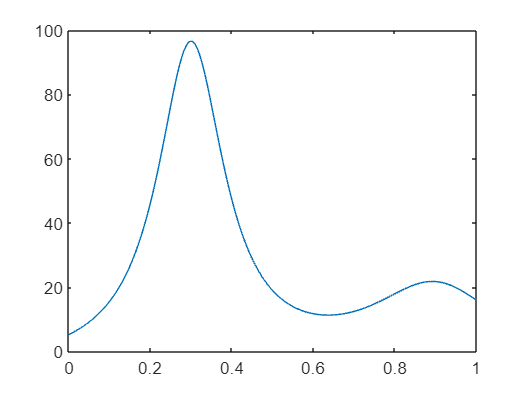

x = 0:.002:1;
y = humps(x);
plot(x,y);

## Datos multivariados

MATLAB utiliza análisis orientado a columnas para datos estadísticos multivariados. Cada columna de un conjunto de datosrepresenta una variable y cada fila una observación. El (i,j)ésimo elemento es la iésima observación dela j-ésima variable.

Como ejemplo, considere un conjunto de datos con tres variables:

• Ritmo cardiaco

• Peso

• Horas de ejercicio por semana    

D = [ 72 134 3.2
 81 201 3.5
 69 156 7.1
 82 148 2.4
 75 170 1.2 ]

D = 5x3
   72.0000  134.0000    3.2000
   81.0000  201.0000    3.5000
   69.0000  156.0000    7.1000
   82.0000  148.0000    2.4000
   75.0000  170.0000    1.2000


La primera fila contiene la frecuencia cardíaca, el peso y las horas de ejercicio del paciente 1, la segunda filacontiene los datos del paciente 2, y así sucesivamente. 

Ahora puede aplicar muchas funciones de análisis de datos de MATLABa este conjunto de datos. Por ejemplo, para obtener la media y la desviación estándar de cada columna, utilice

mu = mean(D), sigma = std(D)

mu = 1x3
   75.8000  161.8000    3.4800


sigma = 1x3
    5.6303   25.4990    2.2107


## Datos perdidos

El valor MATLAB NaN (no es un número) normalmente se usa para representar datos faltantes. Los valores NaN permitenvariables con datos faltantes para mantener su estructura (en este caso, vectores de 24 por 1 con datos consistentes).indexación en las tres intersecciones.

load count.dat

c3 = count(:,3); % Data at intersection 3
c3NaNCount = sum(isnan(c3))

c3NaNCount = 0

## Valores atípicos

Los valores atípicos son valores de datos que son dramáticamente diferentes de los patrones del resto de los datos. Ellospodrían deberse a un error de medición o podrían representar características significativas en los datos.Identificar los valores atípicos y decidir qué hacer con ellos depende de la comprensión de los datos ysu fuente.

 El siguiente código traza un histograma de los datos en el tercerintersección junto con líneas en μ y μ + ησ, para η = 1, 2:

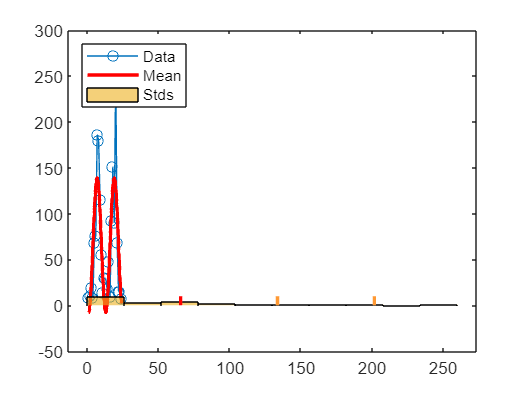

h = histogram(c3,10); % Histogram
N = max(h.Values); % Maximum bin count
mu3 = mean(c3); % Data mean
sigma3 = std(c3); % Data standard deviation
hold on
plot([mu3 mu3],[0 N],'r','LineWidth',2) % Mean
X = repmat(mu3+(1:2)*sigma3,2,1);
Y = repmat([0;N],1,2);
plot(X,Y,'Color',[255 153 51]./255,'LineWidth',2) % Standard deviations
legend('Data','Mean','Stds')
hold off

outliers = (c3 - mu3) > 2*sigma3;
c3m = c3; % Copy c3 to c3m
c3m(outliers) = NaN; % Add NaN values

## Suavizado y filtrado

Un gráfico de series de tiempo de los datos en la tercera intersección (con el valor atípico eliminado en Valores atípicos) da como resultadola siguiente trama:

plot(c3m,'o-')
hold on

El valor de NaN en la hora 20 aparece como un espacio en el gráfico. Este manejo de valores NaN es típico deFunciones de trazado de MATLAB.Los datos ruidosos muestran variaciones aleatorias sobre los valores esperados. Es posible que desee suavizar los datos pararevelar sus características principales antes de construir un modelo. Dos supuestos básicos subyacen al suavizado:

- La relación entre el predictor (tiempo) y la respuesta (volumen de tráfico) es fluida.

- El algoritmo de suavizado da como resultado valores que son mejores estimaciones de los valores esperados porque else ha reducido el ruido.

Aplique una media móvil simple más suave a los datos utilizando la función convn de MATLAB:

span = 3; % Size of the averaging window
window = ones(span,1)/span;
smoothed_c3m = convn(c3m,window,'same');
h = plot(smoothed_c3m,'ro-');
legend('Data','Smoothed Data');

El alcance del suavizado se controla con el span variable. El cálculo del promedio regresaValores de NaN siempre que la ventana de suavizado incluya el valor de NaN en los datos, aumentando así latamaño de la brecha en los datos suavizados.La función de filtro también se utiliza para suavizar datos:

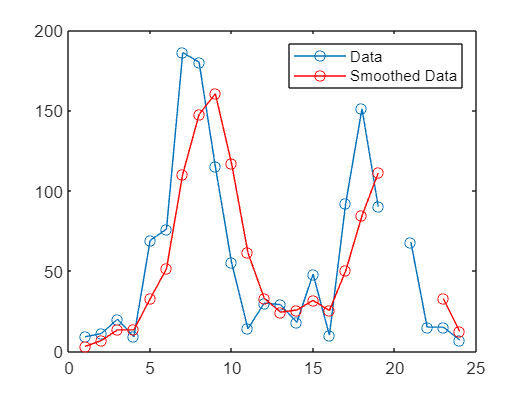

smoothed2_c3m = filter(window,1,c3m);
delete(h)
plot(smoothed2_c3m,'ro-','DisplayName','Smoothed Data');

## Medidas de Ubicación

Resuma la ubicación de una muestra de datos encontrando un valor "típico". Medidas comunes de ubicacióno "tendencia central" se calculan mediante las funciones media, mediana y moda:

load count.dat
x1 = mean(count) 

x1 =    32.0000   46.5417   65.5833


x2 = median(count)

x2 =    23.5000   36.0000   39.0000


x3 = mode(count)

x3 =     11     9     9


## Medidas de escala

Hay muchas formas de medir la escala o "dispersión" de una muestra de datos. Las funciones de MATLAB®max, min, std y var calculan algunas medidas comunes:

dx1 = max(count)-min(count)

dx1 =    107   136   250


dx2 = std(count)

dx2 =    25.3703   41.4057   68.0281


dx3 = var(count)

dx3 = 1.0e+03 *

    0.6437    1.7144    4.6278


## Forma de una distribución

La forma de una distribución es más difícil de resumir que su ubicación o escala. La historia de MATLAB®La función traza un histograma que proporciona un resumen visual:

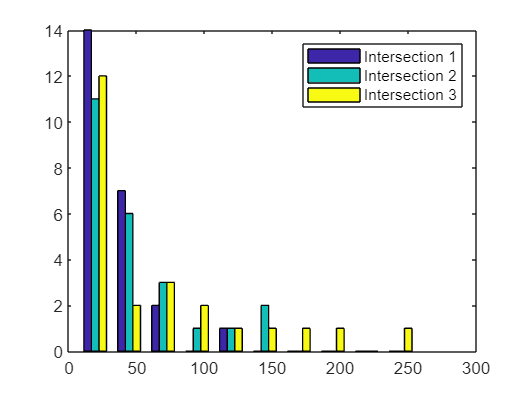

figure
hist(count)
legend('Intersection 1',...
 'Intersection 2',...
 'Intersection 3')

Los modelos paramétricos brindan resúmenes analíticos de las formas de distribución. Distribuciones exponenciales, conEl parámetro mu dado por la media de los datos es una buena opción para los datos de tráfico:

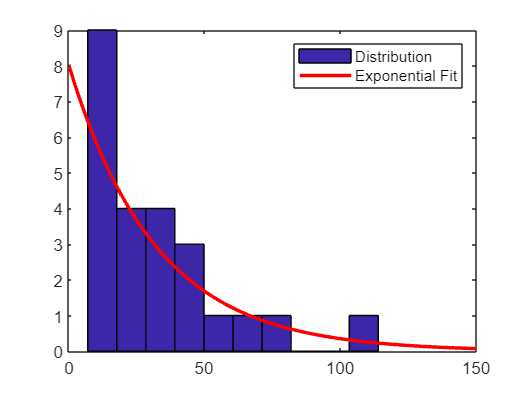

c1 = count(:,1); % Data at intersection 1
[bin_counts,bin_locations] = hist(c1);
bin_width = bin_locations(2) - bin_locations(1);
hist_area = (bin_width)*(sum(bin_counts));
figure
hist(c1)
hold on
mu1 = mean(c1);
exp_pdf = @(t)(1/mu1)*exp(-t/mu1); % Integrates
 % to 1
t = 0:150;
y = exp_pdf(t);
plot(t,(hist_area)*y,'r','LineWidth',2)
legend('Distribution','Exponential Fit')

## Gráficos de dispersión 2-D

Un diagrama de dispersión bidimensional, creado con la función de dispersión, muestra la relación entreel volumen de tráfico en las dos primeras intersecciones:

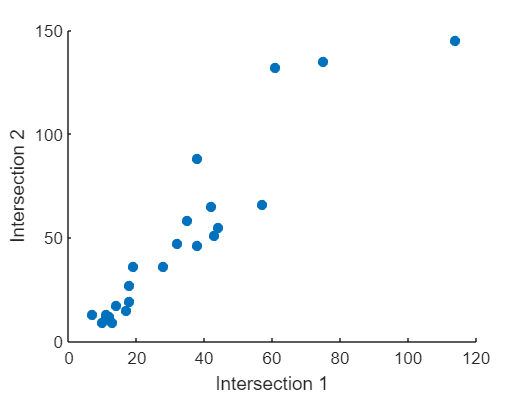

load count.dat
c1 = count(:,1); % Data at intersection 1
c2 = count(:,2); % Data at intersection 2
figure
scatter(c1,c2,'filled')
xlabel('Intersection 1')
ylabel('Intersection 2')

La covarianza, calculada por la función cov, mide la fuerza de la relación lineal.entre las dos variables (qué tan estrechamente se encuentran los datos a lo largo de una línea de mínimos cuadrados que pasa por la dispersión):

C12 = cov([c1 c2])

C12 = 1.0e+03 *

    0.6437    0.9802
    0.9802    1.7144


## Gráficos de dispersión 3D

Un diagrama de dispersión tridimensional, creado con la función scatter3, muestra la relaciónentre el volumen de tráfico en las tres intersecciones. Utilice las variables c1, c2 y c3 quecreado en el paso anterior:

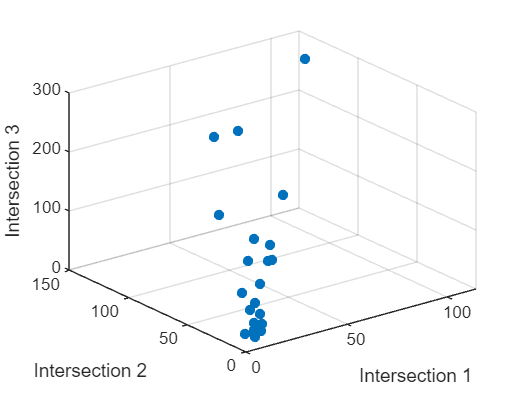


figure
c3 = count(:,3); % Data at intersection 3
scatter3(c1,c2,c3,'filled')
xlabel('Intersection 1')
ylabel('Intersection 2')
zlabel('Intersection 3')    

## Matrices de diagramas de dispersión

Utilice la función plotmatrix para hacer comparaciones de las relaciones entre múltiples pares deintersecciones:

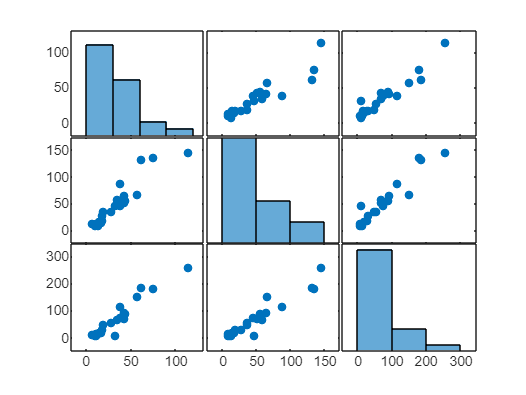


figure
plotmatrix(count)

## Explorando datos en gráficos

Con el mouse, puede seleccionar observaciones en casi cualquier gráfico de MATLAB con dos herramientas de labarra de herramientas de figuras:

•Cursor de datos

•Cepillado de datos

Cada una de estas herramientas lo coloca en modos exploratorios en los que puede seleccionar puntos de datos en gráficos paraidentificar sus valores y crear variables de espacio de trabajo para contener observaciones específicas. cuando usascepillado de datos, también puede copiar, eliminar o reemplazar las observaciones seleccionadas.

Por ejemplo, haga un diagrama de dispersión de la primera y tercera columnas de recuento:

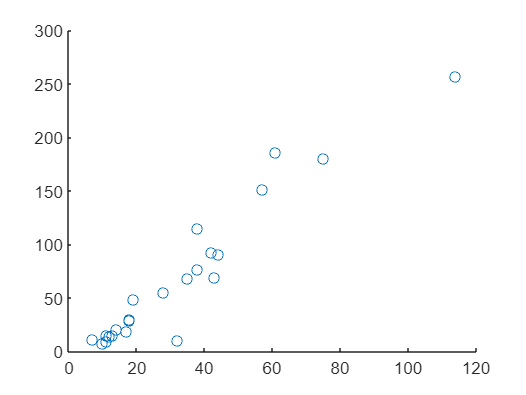

load count.dat
scatter(count(:,1),count(:,3))

Una nueva variable en el espacio de trabajo da como resultado:

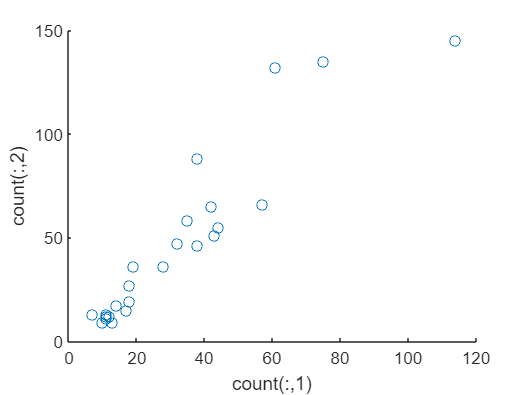

figure
scatter(count(:,1),count(:,2))
xlabel ('count(:,1)')
ylabel ('count(:,2)')

## Regresión polinomial

Utilice la función polyfit para estimar coeficientes de modelos polinomiales, luego utilice la función polivalfunción para evaluar el modelo en valores arbitrarios del predictor.El siguiente código ajusta los datos de tráfico en la tercera intersección con un modelo polinómico de grado seis:

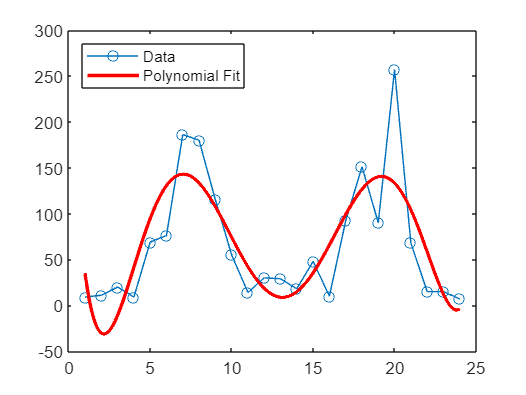

load count.dat
c3 = count(:,3); % Data at intersection 3
tdata = (1:24)';
p_coeffs = polyfit(tdata,c3,6);
figure
plot(c3,'o-')
hold on
tfit = (1:0.01:24)';
yfit = polyval(p_coeffs,tfit);
plot(tfit,yfit,'r-','LineWidth',2)
legend('Data','Polynomial Fit','Location','NW')

## Regresión lineal general

Suponiendo que los datos son periódicos con un período de 12 horas y un pico alrededor de la hora 7, es razonablepara ajustar un modelo sinusoidal de la forma:

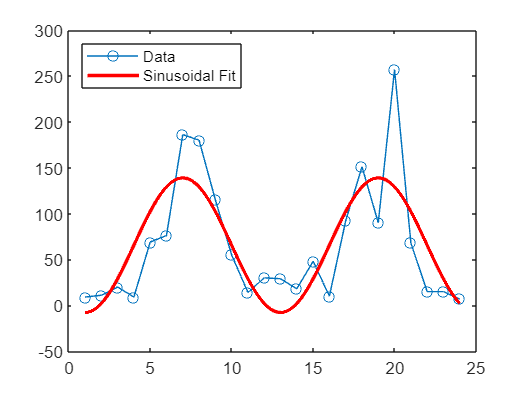

load count.dat
c3 = count(:,3); % Data at intersection 3
tdata = (1:24)';
X = [ones(size(tdata)) cos((2*pi/12)*(tdata-7))];
s_coeffs = X\c3;
figure
plot(c3,'o-')
hold on
tfit = (1:0.01:24)';
yfit = [ones(size(tfit)) cos((2*pi/12)*(tfit-7))]*s_coeffs;
plot(tfit,yfit,'r-','LineWidth',2)
legend('Data','Sinusoidal Fit','Location','NW')

[s_coeffs,stdx,mse] = lscov(X,c3)

s_coeffs =    65.5833
   73.2819


stdx =     8.9185
   12.6127


mse = 1.9090e+03

Verifique el supuesto de un período de 12 horas en los datos con un periodograma, calculado utilizando la fftfunción:

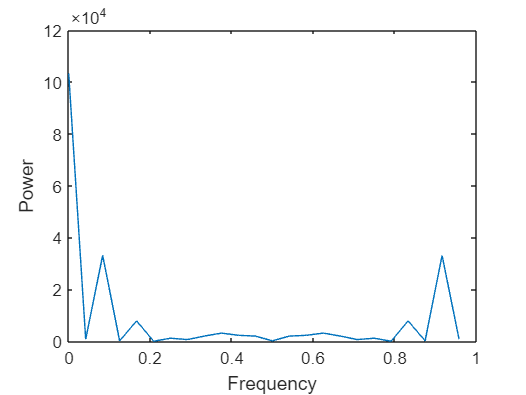

Fs = 1; % Sample frequency (per hour)
n = length(c3); % Window length
Y = fft(c3); % DFT of data
f = (0:n-1)*(Fs/n); % Frequency range
P = Y.*conj(Y)/n; % Power of the DFT
figure
plot(f,P)
xlabel('Frequency')
ylabel('Power')